# **Численные методы в СПб АУ РАН**

## **Задание по практике №7**

Кузьмичев Артём, 4 курс

## **Задание №7**

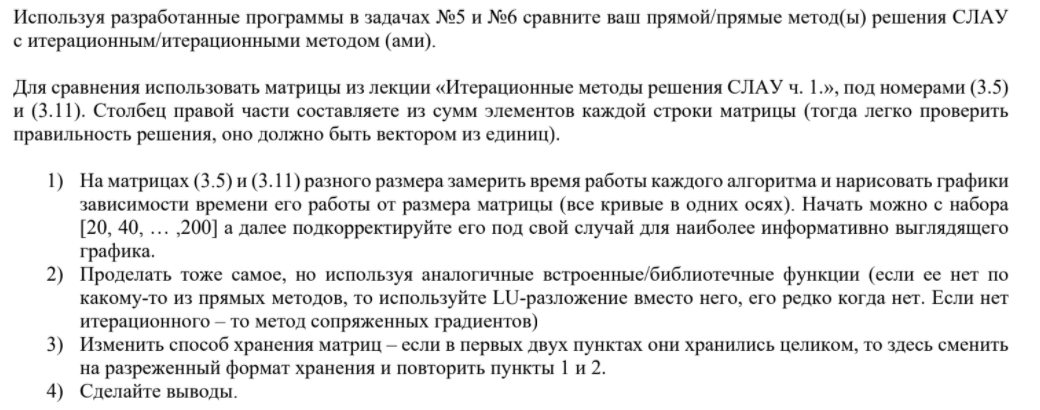

## Введение. Инициализация матриц

Инициализируем трёхдиагональную матрицу $A$ из (3.5), которую мы получили при решении дифференциального уравнения $\frac{d^2 }{\mathrm{d}x^2 }u\left(x\right)=f\left(x\right)$ методом конечных разностей. Так как нам придётся делать это много раз для различных N, инициализация будет осуществляться c помощью функции* band3matrix* (опредление в конце скрипта .mlx) 

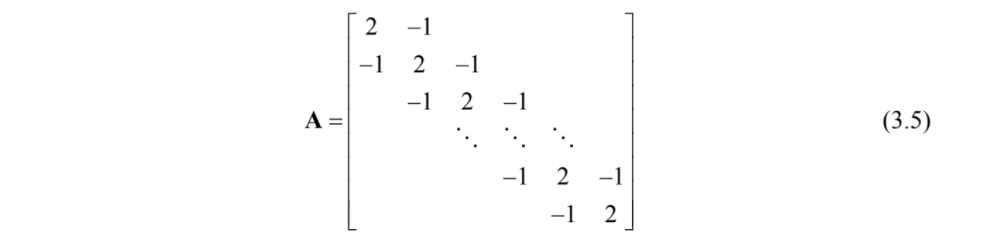

Проверим, что получается именно то, что и было нужно, осуществив для определённого N вывод на экран разреженной матрицы (sparse array) в обычном виде (full-storage)

N = 20;
Adiags = [-1, 2, -1];
A = band3matrix(Adiags, N);
full(A) 

ans =      2    -1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
    -1     2    -1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0    -1     2    -1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0    -1     2    -1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0    -1     2    -1     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0    -1     2    -1     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0    -1     2    -1     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0    -1     2    -1     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0  

Инициализируем матрицу $C$ из (3.11), которую мы получили при решении двумерного уравнения Пуассона $\frac{\partial^2 }{\partial x^2 }u\left(x,y\right)+\frac{\partial^2 }{\partial y^2 }u\left(x,y\right)=f\left(x,y\right)$ методом конечных разностей

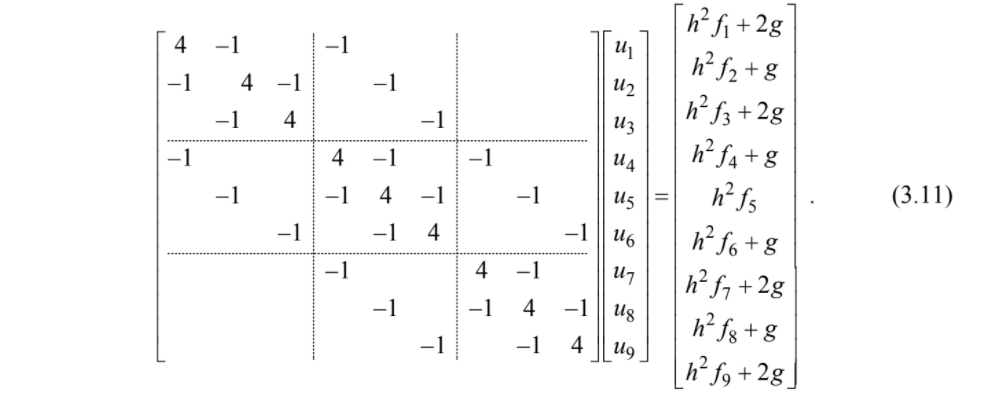

 Для этого зададим матрицу $B=\left\lbrack \begin{array}{ccc}
4 & -1 & 0\\
-1 & 4 & -1\\
0 & -1 & 4
\end{array}\right\rbrack$, повторяющуюся на главной диагонали

BN = 3;
Bdiags = [-1 4 -1];
B = band3matrix(Bdiags, BN);
full(B)

ans =      4    -1     0
    -1     4    -1
     0    -1     4


А также зададим повторяющиеся блоки из минус-единичных матриц. Осуществим построение для определённого N блочной трёхдиагональной матрицы c помощью функции *blktridiag* (опредление в конце скрипта .mlx) 

Так как мы используем общую с матрицей (3.5) размерность N, которая не обязательно кратна 3, разумно будет получать число повторений блоков как $n=\left\lfloor \frac{N}{3}\right\rfloor$Тем не менее, в коде будут использованы значения, приводящие к одинаковым значениям размерности.

n = floor(N/3);
Bsub = -eye(BN);
Bsup = -eye(BN);
C = blktridiag(Bsub, B, Bsup, n);

Проверим, что получилось именно то, что и было нужно, осуществив вывод на экран разреженной матрицы (sparse array) в обычном виде (full-storage)

full(C) 

ans =      4    -1     0    -1     0     0     0     0     0     0     0     0     0     0     0     0     0     0
    -1     4    -1     0    -1     0     0     0     0     0     0     0     0     0     0     0     0     0
     0    -1     4     0     0    -1     0     0     0     0     0     0     0     0     0     0     0     0
    -1     0     0     4    -1     0    -1     0     0     0     0     0     0     0     0     0     0     0
     0    -1     0    -1     4    -1     0    -1     0     0     0     0     0     0     0     0     0     0
     0     0    -1     0    -1     4     0     0    -1     0     0     0     0     0     0     0     0     0
     0     0     0    -1     0     0     4    -1     0    -1     0     0     0     0     0     0     0     0
     0     0     0     0    -1     0    -1     4    -1     0    -1     0     0     0     0     0     0     0
     0     0     0     0     0    -1     0    -1     4     0     0    -1     0     0     0     0     0     0
     0     0 

## Сравнение производительности

Будем инициализировать матрицу, а затем получать вектор правой части просто как сумму по строкам $b^i =\sum_{k=1}^N a_k^i$. Тогда очевидно, что решением системы будет вектор единиц, в связи с чем упростится проверка. 

#### *Диапазон изменения значений размерности матриц. *

Nmin = 30;
Nmax = 300;
Nstep = 30;
Nrange = Nmin:Nstep:Nmax;

Чтобы хранить зависимости времени от размерности, создадим списки. Можно было бы и тензором, но в ущерб наглядности

l = length(Nrange);

A_sparse_lusolve_time = zeros(1,l);         % А - sparse. Решение самостоятельно написанной функцией lusolve() - LUP-декомпозиция
A_sparse_conjgrad_time = zeros(1,l);        % А - sparse. Решение самостоятельно написанной функцией conjgrad() - метод сопряженных градиентов
A_sparse_pcg_time = zeros(1,l);             % А - sparse. Решение in-built pcg()

A_fullst_lusolve_time = zeros(1,l);         % А - full-storage. Решение самостоятельно написанной функцией lusolve() - LUP-декомпозиция
A_fullst_conjgrad_time = zeros(1,l);        % А - full-storage. Решение самостоятельно написанной функцией conjgrad() - метод сопряженных градиентов
A_fullst_linsolve_time = zeros(1,l);        % А - full-storage. Решение in-built linsolve()
A_fullst_pcg_time = zeros(1,l);             % А - full-storage. Решение in-built pcg()

C_sparse_lusolve_time = zeros(1,l);         % C - sparse. Решение самостоятельно написанной функцией lusolve() - LUP-декомпозиция
C_sparse_conjgrad_time = zeros(1,l);        % C - sparse. Решение самостоятельно написанной функцией conjgrad() - метод сопряженных градиентов
C_sparse_pcg_time = zeros(1,l);             % C - sparse. Решение in-built pcg()

C_fullst_lusolve_time = zeros(1,l);         % C - full-storage. Решение самостоятельно написанной функцией lusolve() - LUP-декомпозиция
C_fullst_conjgrad_time = zeros(1,l);        % C - full-storage. Решение самостоятельно написанной функцией conjgrad() - метод сопряженных градиентов
C_fullst_linsolve_time = zeros(1,l);        % C - full-storage. Решение in-built linsolve()
C_fullst_pcg_time = zeros(1,l);             % C - full-storage. Решение in-built pcg()

Количество повторений решения СЛАУ, на основании которых замеренное время будет усредняться:

AN = 40;

Параметры используемого pcg и conjgrad - точность и максимальное число итераций:

tol = 1e-7;
maxit = 400;

## **Цикл**

for i = 1:l
    
    N = Nrange(i);
    fprintf('N = %d \n', N);
    
    % инициализация матрицы A
    Adiags = [-1, 2, -1];
    A = band3matrix(Adiags, N);
    b = sum(A,2);

В этой части цикла используется матрица A в разреженном формате

    % A , sparce, lusolve
    tic
    for j =1:AN
        [LU, R] = lufact(A);
        X = lusolve(LU,R,b);
    end
    A_sparse_lusolve_time(i) = toc/AN;
    
    % A , sparce, conjgrad
    tic
    for j =1:AN
    X = conjgrad(A, b, tol, maxit);
    end
    A_sparse_conjgrad_time(i) = toc/AN;
    
    % A , sparce, pcg
    tic
    for j =1:AN
    [X,flag] = pcg(A, b, tol, maxit); 
    end
    A_sparse_pcg_time(i) = toc/AN;

В этой части цикла используется матрица A в full-storage формате

    A = full(A);
    b = full(b);
   
    % A , full-storage, lusolve
    tic
    for j =1:AN
    [LU, R] = lufact(A);
    X = lusolve(LU,R,b);
    end
    A_fullst_lusolve_time(i) = toc/AN;
    
    % A , full-storage, conjgrad
    tic
    for j =1:AN
    X = conjgrad(A, b, tol, maxit);
    end
    A_fullst_conjgrad_time(i) = toc/AN;
    
    % A , full-storage, linsolve
    tic
    for j =1:AN
    X = linsolve(A,b);
    end
    A_fullst_linsolve_time(i) = toc/AN;
    
    % A , full-storage, pcg
    tic
    for j =1:AN
    [X,flag] = pcg(A, b, tol, maxit);
    end
    A_fullst_pcg_time(i) = toc/AN;

В этой части цикла используется матрица C в разреженном формате

    % инициализация матрицы C %
    n = floor(N/3);
    C = blktridiag(Bsub, B, Bsup, n);
    b = sum(C,2);
   
    % C , sparce, lusolve
    tic
    for j =1:AN
    [LU, R] = lufact(C);
    X = lusolve(LU,R,b);
    end
    C_sparse_lusolve_time(i) = toc/AN;
    
    % C , sparce, conjgrad
    tic
    for j =1:AN
    X = conjgrad(C, b, tol, maxit);
    end
    C_sparse_conjgrad_time(i) = toc/AN;
    
    % C , sparce, pcg
    tic
    for j =1:AN
    [X,flag] = pcg(C, b, tol, maxit);
    end
    C_sparse_pcg_time(i) = toc/AN;

В этой части цикла используется матрица C в full-storage формате

    C = full(C);
    b = full(b);
    
    % C , full-storage, lusolve
    tic
    for j =1:AN
    [LU, R] = lufact(C);
    X = lusolve(LU,R,b);
    end
    C_fullst_lusolve_time(i) = toc/AN;
    
    % C , full-storage, conjgrad
    tic
    for j =1:AN
    X = conjgrad(C, b, tol, maxit);
    end
    C_fullst_conjgrad_time(i) = toc/AN;
    
    % C , full-storage, linsolve
    tic
    for j =1:AN
    X = linsolve(C,b);
    end
    C_fullst_linsolve_time(i) = toc/AN;
    
    % C , full-storage, pcg
    tic
    for j =1:AN
    [X,flag] = pcg(C, b, tol, maxit);
    end
    C_fullst_pcg_time(i) = toc/AN;
end

N = 30 
N = 60 
N = 90 
N = 120 
N = 150 
N = 180 
N = 210 
N = 240 
N = 270 
N = 300 


Сохраним/загрузим данные, так как цикл выше считается очень долго ( При N=30:30:450, AN = 30  $\left.T_{\mathrm{all}} \approx 20\;\mathrm{мин}\right)$

save ('n30_30_300_an40.dat');

Построим графики:

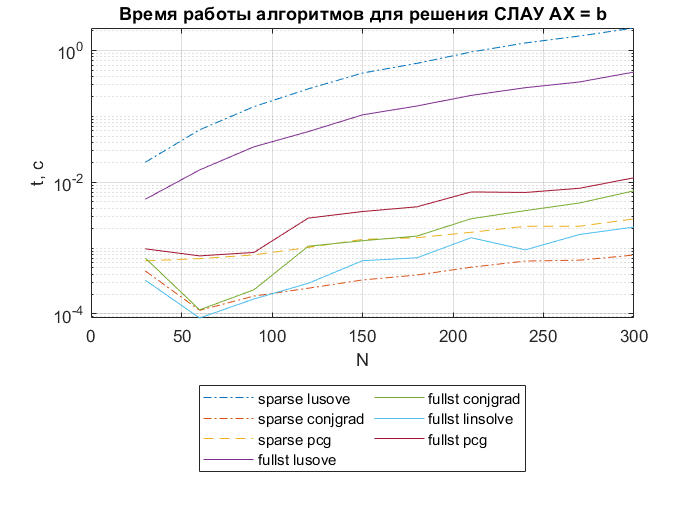

semilogy(Nrange, A_sparse_lusolve_time,'-.')
grid on;
hold on;
semilogy(Nrange, A_sparse_conjgrad_time,'-.')
semilogy(Nrange, A_sparse_pcg_time,'--')

semilogy(Nrange, A_fullst_lusolve_time)
semilogy(Nrange, A_fullst_conjgrad_time)
semilogy(Nrange, A_fullst_linsolve_time)
semilogy(Nrange, A_fullst_pcg_time)

title('Время работы алгоритмов для решения СЛАУ AX = b');
legend({'sparse lusove','sparse conjgrad','sparse pcg' ...
    'fullst lusove','fullst conjgrad','fullst linsolve','fullst pcg'}, ...
    'Location','southoutside','NumColumns',2)
xlabel('N');
ylabel('t, с');

hold off;

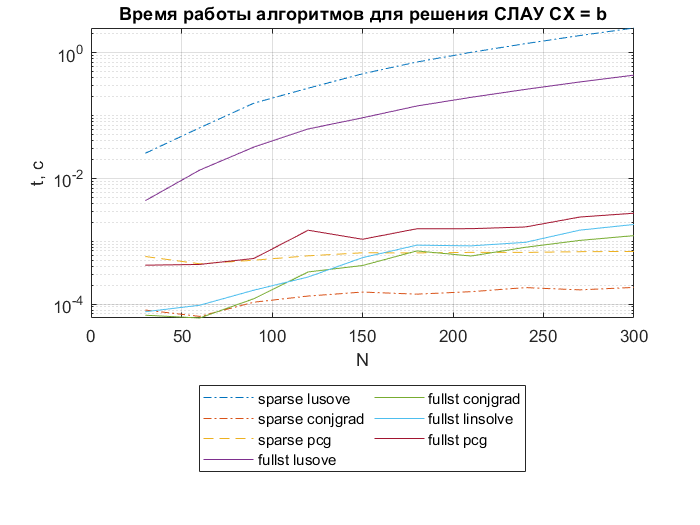


semilogy(Nrange, C_sparse_lusolve_time,'-.')
grid on;
hold on;
semilogy(Nrange, C_sparse_conjgrad_time,'-.')
semilogy(Nrange, C_sparse_pcg_time,'--')

semilogy(Nrange, C_fullst_lusolve_time)
semilogy(Nrange, C_fullst_conjgrad_time)
semilogy(Nrange, C_fullst_linsolve_time)
semilogy(Nrange, C_fullst_pcg_time)

title('Время работы алгоритмов для решения СЛАУ CX = b');
legend({'sparse lusove','sparse conjgrad','sparse pcg' ...
    'fullst lusove','fullst conjgrad','fullst linsolve','fullst pcg'}, ...
    'Location','southoutside','NumColumns',2);
xlabel('N');
ylabel('t, с');

## Выводы

- Время вычисления алгоритмов растёт с увеличением размеров матрицы.

- Прямые алгоритмы более требовательны ко времени, чем итеративные.

- В большинстве случаёв разреженное хранение матрицы (*sparce array*) даёт выигрыш в скорости. *Исключение связано с LU-разложением, которое, впрочем, показало самые медленые результаты*

- Нельзя сказать, что встроенные функции сильно отличаются от реализованных вручную алгоритмов. *Использование встроенных функций в любом случае предпочтительней, т.к. гарантируется корректность алгоритма*

## Приложение

#### Определение функции, осуществляющей построение ленточной трёхдиагональной матрицы

function A = band3matrix(v, N)
%Вход   -   N   - размер матрицы
%       -   v   - список 1 х 3 c элементами трёхдиагональной матрицы
%Выход  -   A - трёхдиагональная разреженная матрица

columnarray = repelem(v,[N],[1]);
A = spdiags(columnarray,-1:1,N,N);
end

#### Определение функции, осуществляющей построение блочно-трёхдиагональной матрицы

function BTD = blktridiag(Bsub, B, Bsup, n)
%Вход   -   Bsub - матрица p x q, которую необходимо разместить под главной диагональю
%Вход   -   B    - матрица p x q, которую необходимо разместить на главной диагонали
%       -   Bsup - матрица p x q, которую необходимо разместить над главной диагональю
%       -   n    - число повторений блоков
%Выход  -   BTD  - блочно-трёхдиагональная матрица

[p,q] = size(B);

%Создание массива повторением матриц
v = repmat(B(:),n,1);
v=[v;repmat(Bsub(:),n-1,1)];
v=[v;repmat(Bsup(:),n-1,1)];

%Индексирование массива
[ind1,ind2,ind3]=ndgrid(0:p-1,0:q-1,0:n-1);
rind = 1+ind1(:)+p*ind3(:);
cind = 1+ind2(:)+q*ind3(:);

if n>1
    % sub-diagonal
    [ind1,ind2,ind3]=ndgrid(0:p-1,0:q-1,0:n-2);
    rind = [rind;1+p+ind1(:)+p*ind3(:)];
    cind = [cind;1+ind2(:)+q*ind3(:)];
    
    % super-diagonal
    rind = [rind;1+ind1(:)+p*ind3(:)];
    cind = [cind;1+q+ind2(:)+q*ind3(:)];
end

% Получившаяся соответсвующим индексированием разреженная матрица
BTD = sparse(rind,cind,v,n*p,n*q);
end

#### Определение функции, осуществляющей LU-разложение

function [LU, R] = lufact(A)
%Вход  - А  - матрица размера N x N
%Выход - LU - матрица размера N x N, в которой выше диагонали указаны
%элементы U, а ниже диагонали - недиагональные элементы L
%      - R  - строка перестановок 1 x N

%Инициализация
[~,N]=size(A);
C=zeros(1,N);
R=1:N;
LU = A;

for p=1:N-1
    [~,j]=max(abs(LU(p:N,p))); %Главный элемент строки для столбца р
    
    %Замена строк
    C=LU(p,:);
    LU(p,:)=LU(j+p-1,:);
    LU(j+p-1,:)=C;
    
    %Учёт соответствующей замены строк в перестановку R
    d=R(p);
    R(p)=R(j+p-1);
    R(j+p-1)=d;
    
    if LU(p,p)==0
        disp('Матрица А вырождена. Нет единственного решения');
        break
    end
    
    %Вычисление множителя и размещение под диагональю матрицы LU
    for k=p+1:N
        mult=LU(k,p)/LU(p,p);
        LU(k,p) = mult;
        LU(k,p+1:N)=LU(k,p+1:N)-mult*LU(p,p+1:N);
    end
end
end

#### Определение функции, осуществляющей решение системы вида LUX = b

function X = lusolve(LU,R,b)
%Вход  - LU - матрица размера N x N, в которой выше диагонали указаны элементы U, а ниже диагонали - недиагональные элементы L
%      - R  - строка перестановок 1 x N
%      - b  - столбец правой части СЛАУ N x 1
%Выход - X  - столбец решения СЛАУ

[~,N]=size(LU);

%Решение для Y
Y=zeros(N,1);
Y(1) = b(R(1));
for k=2:N
    Y(k)= b(R(k))-LU(k,1:k-1)*Y(1:k-1);
end

%Решение для Х
X=zeros(N,1);
X(N)=Y(N)/LU(N,N);
for k=N-1:-1:1
    X(k)=(Y(k)-LU(k,k+1:N)*X(k+1:N))/LU(k,k);
end

end

#### Определение функции, осуществляющей решение СЛАУ методом сопряженных градиентов

function X = conjgrad(A, b, tol, maxit) 
%Вход   -   A   - симметричная положительно определённая матрица N x N
%       -   b   - столбец N x 1 - правая часть СЛАУ
%       -   tol - значение невязки, при котором итерации останавливаются
%       -   maxit - максимальное число итераций
%Выход  -   X   - столбец решения СЛАУ

% начальное приближение
X = zeros(size(b));
r = b - A*X;
p = r; 
rsold = r' * r; 

for i=1:maxit
    Ap = A * p;
    alpha = rsold / (p' * Ap); 
    X = X + alpha * p; 
    r = r - alpha * Ap; 
    rsnew = r' * r; 
    rrel = sqrt(rsnew)/norm(b);
    if rrel < tol
        break;
    end 
    p = r + (rsnew / rsold) * p; 
    rsold = rsnew;
end

end